# HW4

First remove all open background.

close all;
clear;
clc;

## 1

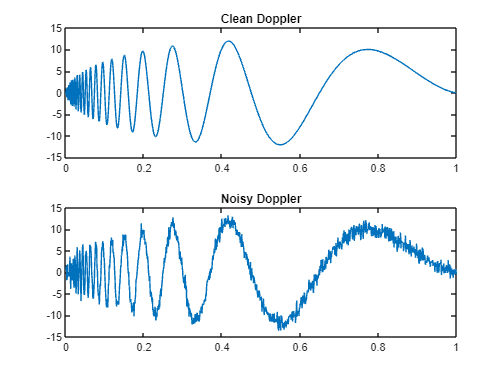

loc = linspace(0,1,2^10);
[x, noisyx] = wnoise('doppler',10,7);
figure('Name', 'Figure1');
subplot(2,1,1)
plot(loc,x)
title('Clean Doppler')
ylim([-15 15])
subplot(2,1,2)
plot(loc, noisyx)
title('Noisy Doppler')
ylim([-15 15])

## 2

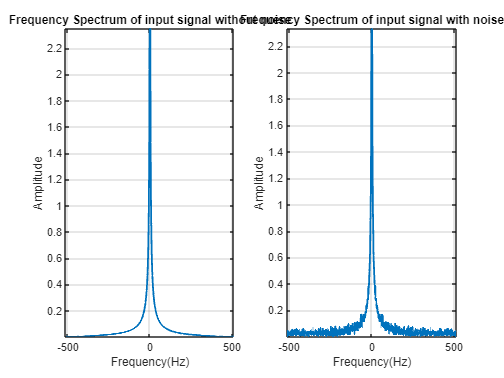

Ts = loc(2) - loc(1);
fs = 1 / Ts;
figure('Name', 'Figure 2');
subplot(121);
plot_dft_amp(x, fs, 'Frequency Spectrum of input signal without noise');
subplot(122);
plot_dft_amp(noisyx, fs, 'Frequency Spectrum of input signal with noise');

## 3

The following code uses the `dwt` function to decompose the noisy signal to approximation and detail coefficients using the db10 wavelet.

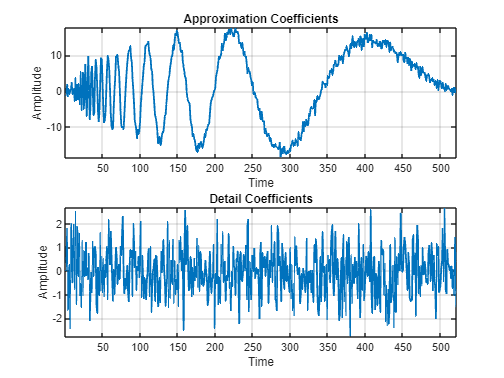

[cA, cD] = dwt(noisyx, 'db10');
figure('Name', 'Approximation and Detail Coefficients');
subplot(211);
plot(cA, 'LineWidth', 1.5);  % can use stem instead of plot
title('Approximation Coefficients');
xlabel('Time');
ylabel('Amplitude');
grid on;
axis tight;
subplot(212);
plot(cD, 'LineWidth', 1.5);
title('Detail Coefficients');
xlabel('Time');
ylabel('Amplitude');
grid on;
axis tight;

#### 4

The following code uses the `wavedec` function to decompose the noisy signal to 10 levels of decomposition using the db8 wavelet.

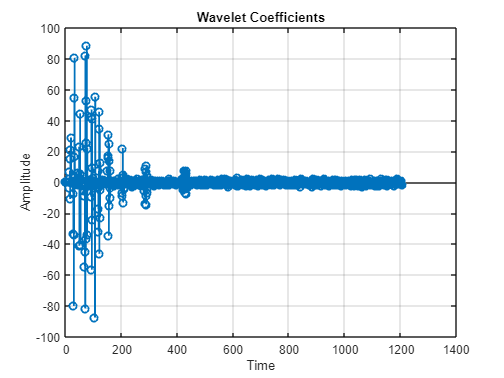

numberOfLevels = 10;
[waveletCoefficients, waveletLevels] = wavedec(noisyx, numberOfLevels, 'db10');
figure('Name', 'Wavelet Coefficients');
stem(waveletCoefficients, 'LineWidth', 1.5);
title('Wavelet Coefficients');
xlabel('Time');
ylabel('Amplitude');
grid on;

#### 5

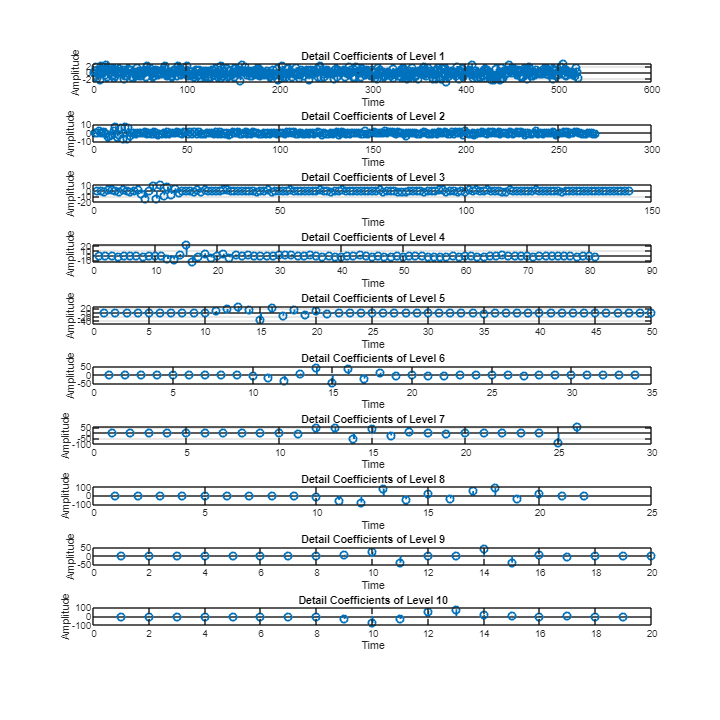

detailed_coeff = detcoef(waveletCoefficients, waveletLevels, 1: numberOfLevels);
figure('Name', 'Wavelet Coefficients of Different Levels');
set(gcf, 'Position', [100, 100, 1000, 1000]);

for i = 1: numberOfLevels
    subplot(numberOfLevels, 1, i);
    stem(detailed_coeff{i}, 'LineWidth', 1.5);
    title(['Detail Coefficients of Level ', num2str(i)]);
    xlabel('Time');
    ylabel('Amplitude');
    grid on;
end

#### 6

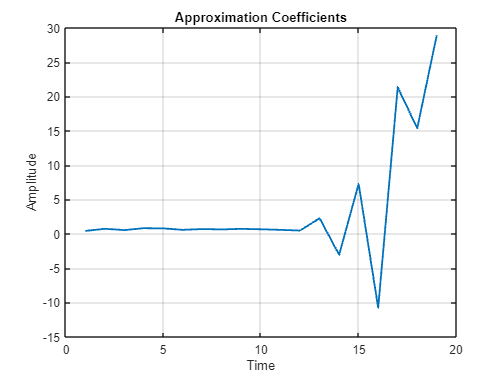

approx_coeff = appcoef(waveletCoefficients, waveletLevels, 'db10', 10);
figure('Name', 'Approximation Coefficients');
plot(approx_coeff, 'LineWidth', 1.5);
title('Approximation Coefficients');
xlabel('Time');
ylabel('Amplitude');
grid on;

#### 7 & 8

approx_coeff_deepest_layer = appcoef( ...
    waveletCoefficients, ...
    waveletLevels, ...
    'db10', ...
    numberOfLevels ...
);

extract the detail coefficients of different layers and concatenate them.

wavelet_coefficients_regenerated = ...
    [approx_coeff_deepest_layer, detailed_coeff{numberOfLevels:-1:1}];

Now we should compare the regenerated wavelet coefficients with the original wavelet coefficients.

fprintf("\nError: %d\n", ...
    sum(abs(wavelet_coefficients_regenerated - waveletCoefficients)));


Error: 8.563155e+02


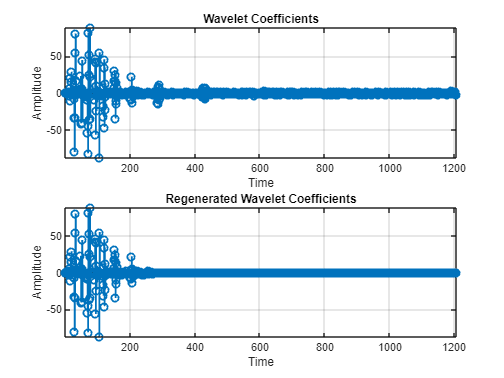


figure('Name', 'Wavelet Coefficients vs Regenerated Wavelet Coefficients');
subplot(211);
stem(waveletCoefficients, 'LineWidth', 1.5);
title('Wavelet Coefficients');
xlabel('Time');
ylabel('Amplitude');
grid on;
axis tight;
subplot(212);
stem(wavelet_coefficients_regenerated, 'LineWidth', 1.5);
title('Regenerated Wavelet Coefficients');
xlabel('Time');
ylabel('Amplitude');
grid on;
axis tight;

#### 9

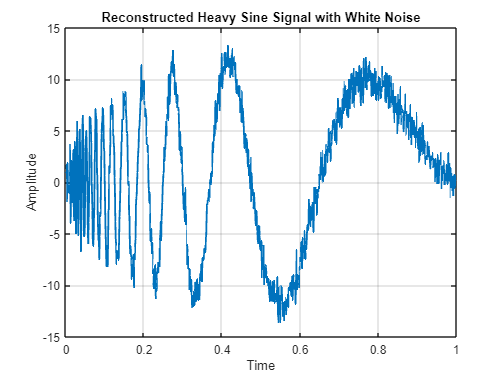

reconstructed_x = waverec(waveletCoefficients, waveletLevels, 'db10');
figure('Name', 'Reconstructed Heavy Sine Signal with White Noise');
plot(loc, reconstructed_x, 'LineWidth', 1.5);
title('Reconstructed Heavy Sine Signal with White Noise');
xlabel('Time');
ylabel('Amplitude');
grid on;

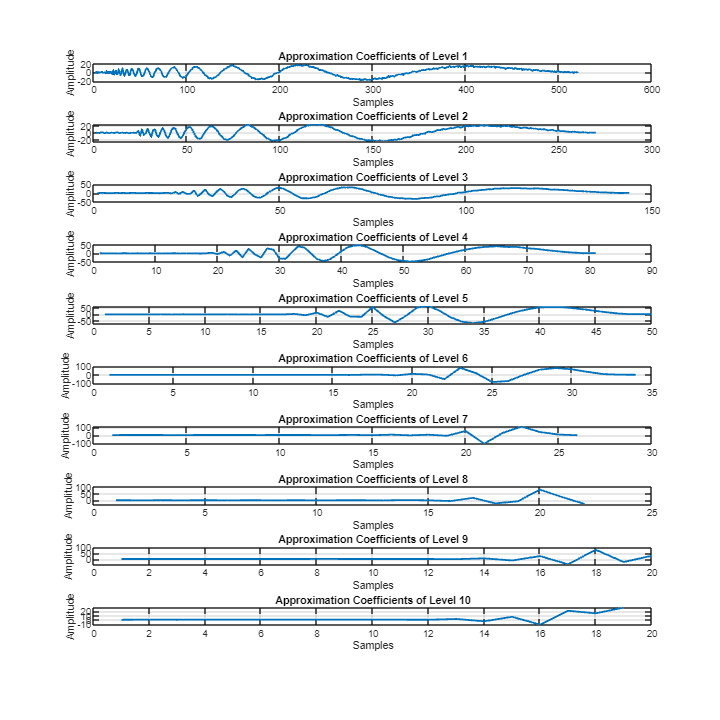


[Ea, Ed] = wenergy(waveletCoefficients, waveletLevels);

detail_coeff_noise_std = wnoisest(waveletCoefficients, waveletLevels, 1:numberOfLevels);

figure('Name', 'Approximation Coefficients of Different Levels');
for level = 1:numberOfLevels
    subplot(numberOfLevels, 1, level);
    set(gcf, 'Position', [100, 100, 1000, 1000]);
    approx = appcoef(waveletCoefficients, waveletLevels, 'db10', level);
    plot(approx, 'LineWidth', 1.5);
    title(['Approximation Coefficients of Level ', num2str(level)]);
    xlabel('Samples');
    ylabel('Amplitude');
    grid on;
end

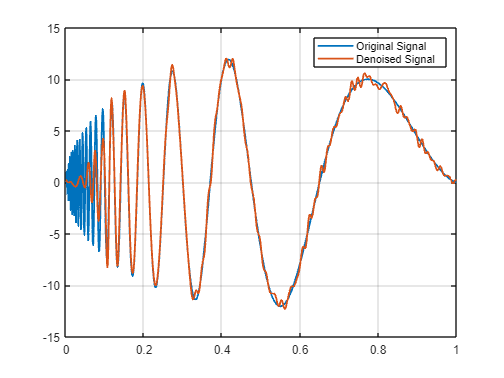


for level = 1:3
    detailed_coeff{level} = zeros(size(detailed_coeff{level}));
end

wavelet_coefficients_denoised = ...
    [approx_coeff_deepest_layer, detailed_coeff{numberOfLevels:-1:1}];

x_denoised = waverec(wavelet_coefficients_denoised, waveletLevels, 'db10');
figure('Name', 'Denoised Heavy Sine Signal');
title('Denoised Heavy Sine Signal');
xlabel('Time');
ylabel('Amplitude');
plot(loc, x, 'LineWidth', 1.5);
hold on;
grid on;
plot(loc, x_denoised, 'LineWidth', 1.5);
legend('Original Signal', 'Denoised Signal');

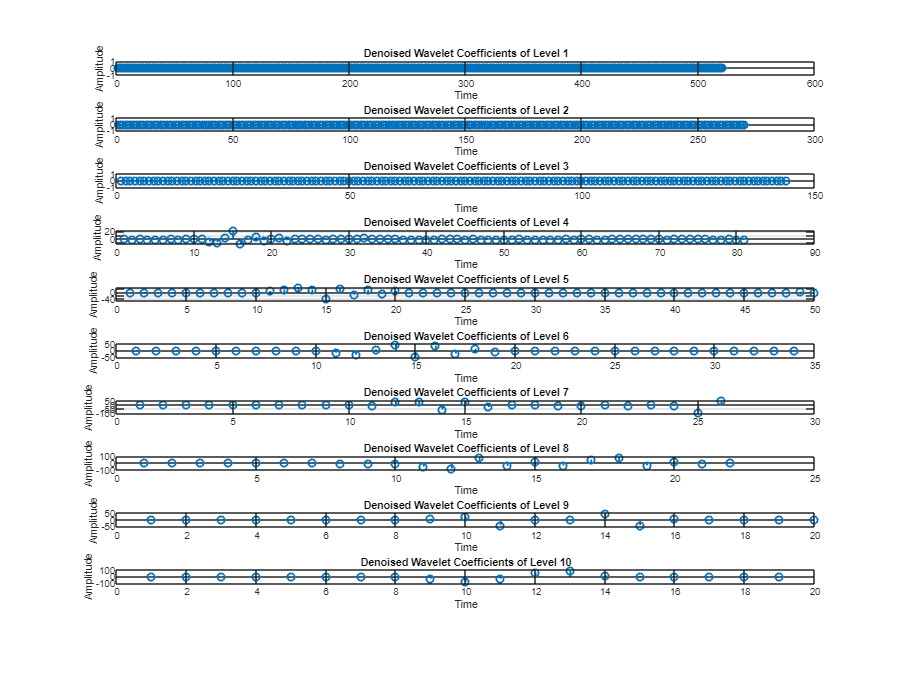


figure('Name', 'Denoised Wavelet Coefficients of Different Levels');
set(gcf, 'Position', [100, 100, 1000, 1000]);

for i = 1:numberOfLevels
    subplot(numberOfLevels, 1, i);
    stem(detailed_coeff{i}, 'LineWidth', 1.5);
    title(['Denoised Wavelet Coefficients of Level ', num2str(i)]);
    xlabel('Time');
    ylabel('Amplitude');
    grid on;
end

because, as we know this function act like inverse wavedec function there is a possible messure that we miss some data so there is not proper in this case for denoising the signal.

#### 10

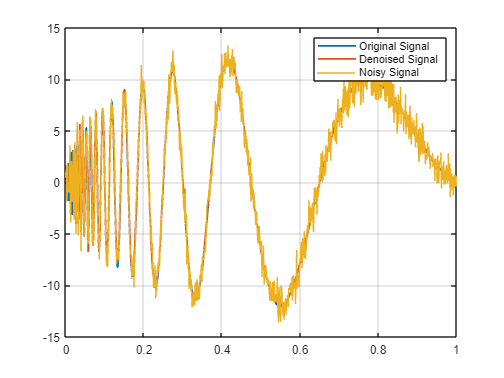

denoised_x = wdenoise(noisyx, 10, Wavelet = 'db10');
figure('Name', 'Heavy Sine Signal with White Noise vs Denoised Heavy Sine Signal');

title('Denoised Heavy Sine Signal');
xlabel('Time');
ylabel('Amplitude');
plot(loc, x, 'LineWidth', 1.5);
grid on;
hold on;
plot(loc, denoised_x, 'LineWidth', 1.5);
plot(loc, noisyx, 'LineWidth', 0.5);
legend('Original Signal', 'Denoised Signal', 'Noisy Signal');

## Functions

We used the following function to plot differnt plots with an arbitrary title:

function plot_dft_amp(x, fs, title_name)
    f_axis = linspace(-fs / 2, fs / 2, length(x));
    FT_x = fftshift(fft(x)) / fs;
    plot(f_axis, abs(FT_x), 'LineWidth', 1.5);
    xlabel('Frequency(Hz)');
    title(title_name);
    ylabel('Amplitude');
    axis tight;
    grid on;
end